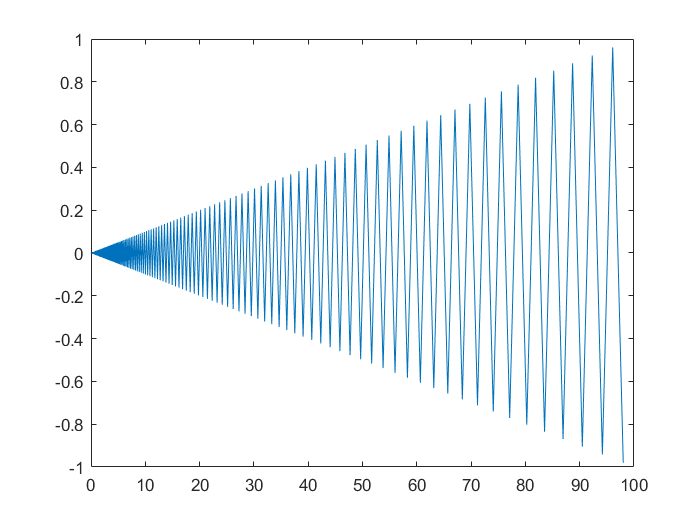

clc
clear all

syms x1 x2;
f = x1 ^ 2 / 2 + 50 * x2 ^ 2;
x = [100; 1];
epsilon = 1e-8;
t = 2 / 101;
x1_ax = [];
x2_ax = [];
f_ax = [];

d = -[diff(f,x1);diff(f,x2)];
flag = 1;
k = 0; 
while(flag)
    d_temp = subs(d,x1,x(1));      
    d_temp = subs(d_temp,x2,x(2));
    nor = norm(d_temp);
    if(nor >= epsilon)
        x = x + t * d_temp;
        x = double(x);
        x1_ax = [x1_ax, x(1)];
        x2_ax = [x2_ax, x(2)];
        f_ax = [f_ax, double(subs(subs(f,x1,x(1)),x2,x(2)))];
        k = k + 1;
    else
        flag=0;
    end
end
plot(x1_ax,x2_ax)

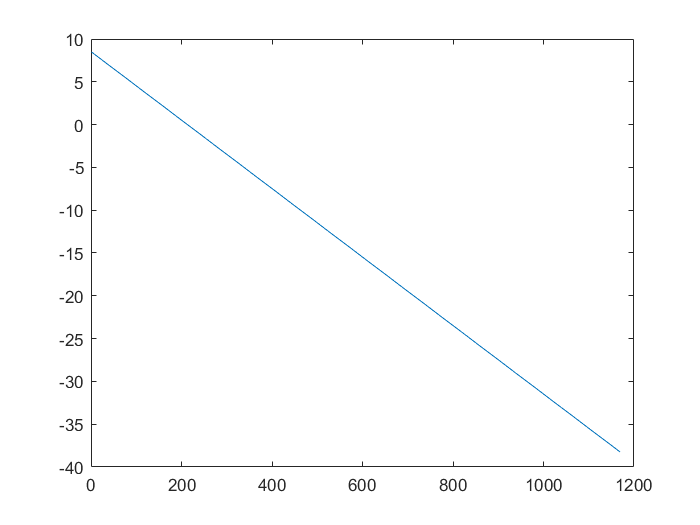

plot(log(f_ax))